# Optimization and Data Analytics HW11

## An Introduction to Optimization sec. 14

## Exercise 14.2

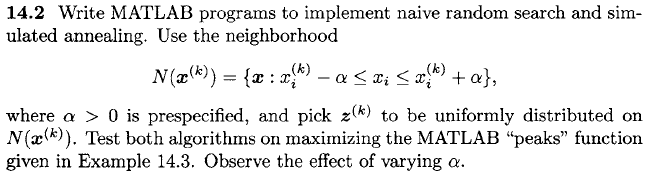

The assumption is that the goal is to find the **minimum** of the specified function.

The function is defined as:

f = @(x,y) 3*(1-x).^2 .* exp(-x.^2-(y+1).^2) - 10*(x.*0.2-x.^3-y.^5).*exp(-x.^2-y.^2) - exp(-(x+1).^2-y.^2)/3;

% Plot in relevant interval
lower_bound = -3;
upper_bound = 3;
res = .1;
[x, y] = meshgrid(lower_bound:res:upper_bound,lower_bound:res:upper_bound);
z = f(x, y);
close all;
figure(1)
surf(x, y, z);
xlabel('X');
ylabel('Y');
zlabel('Z');

% Variable to hold figure handles for use later
h_naive = 0;
h_anneal = 0;
h_anneal_best = 0;

hold on

The neighborhood range function is defined:

N = @(x,a) [x-a x+a];

Selecting a random point from the neighborhood range is then done by:

rp = @(x,a) (x-a)+2*a*rand(1);

## Naive Random Search

Defining the value of $\alpha$determines the volatility of the algorithm. $\alpha$determines the range of neighboring values which are considered as candidates, and thereby determines the tendency of the algorithm to escape local minimums.

alpha = 2.8;

***Step 1:***

An initial point is selected:

k = 0;

% randomized index of x range
[m, n] = size(x);
x = x(1,randi(m));

% randomized index of y range
[m, n] = size(y);
y = y(randi(m),1);

% randomly selected point
x_k = [x; y];

% point evaluation
min = f(x_k(1),x_k(2));

***Iterations (Step 2, 3, 4 and 5):***

The neighborhood range is determined and a random point within the neighborhood is selected and evaluated.

It is important to note that the *peaks* function approaches zero as x and y move outside the specified range of [-3;3], but never reaches exactly zero. The algorithm can therefore end up continuing outwards when minimizing. The values of x and y are constrained to the bounds of the function to avoid this.

iteration_limit = 150;
for i=0:iteration_limit
    k = i;
    
    % Step 2: Pick Neighborhood point
    x_cur = rp(x_k(1),alpha);
    y_cur = rp(x_k(2),alpha);
    
    % Constrain values of x and y to the bounds of the function
    if (x_cur < lower_bound)
        x_cur = lower_bound;
    elseif (x_cur > upper_bound)
        x_cur = upper_bound;
    end
    
    if (y_cur < lower_bound)
        y_cur = lower_bound;
    elseif (y_cur > upper_bound)
        y_cur = upper_bound;
    end
    
    % Step 3: Evaluate function at selected point and update current best
    min_cur = f(x_cur,y_cur);
    if (min_cur < min)
       x_k = [x_cur; y_cur];
       min = min_cur;
       h_naive = scatter3(x_k(1), x_k(2), min, '*y');
    end
end
disp('Naive Random Search')

Naive Random Search


fprintf('Iterations: %d\n',iteration_limit);

Iterations: 150


fprintf('Minimum found %f at (x,y)=(%f,%f)',min,x_k(1),x_k(2));

Minimum found 0.000041 at (x,y)=(3.000000,3.000000)

## Simulated Annealing

The cooling schedule determines the volatility of the algorithm, which is its ability to escape local minimums.

A suggested approach to the cooling schedule is:


$$T_k=\frac{\gamma}{log(k+2)}$$


Using this approach, $\gamma$ determines the cooling schedule and must be greater than zero, but is otherwise chosen based on the properties of the objective function:


$$\gamma > 0$$


gamma = 0.9;

The cooling schedule is then:

T_k = @(g,k) g/log(k+2);

The probability of selecting an inferior point is given by:

pr = @(z,x,temp) exp(-(f(z(1),z(2))-f(x(1),x(2)))/temp);

***Step 1:***

An initial point is selected:

k = 0;

% randomized index of x range
[m, n] = size(x);
x = x(1,randi(m));

% randomized index of y range
[m, n] = size(y);
y = y(randi(m),1);

% randomly selected point
x_k = [x; y];
x_best = x_k;

% point evaluation
min = f(x_k(1),x_k(2));

***Iterations (Step 2, 3, 4 and 5):***

The neighborhood range is determined and a random point within the neighborhood is selected and evaluated.

It is important to note that the *peaks* function approaches zero as x and y move outside the specified range of [-3;3], but never reaches exactly zero. The algorithm can therefore end up continuing outwards when minimizing. The values of x and y are constrained to the bounds of the function to avoid this.

In addition, the cooling schedule is used to calculate a temperature for each iteration, which is then used to calculate a probability of selecting an inferior neighbour.

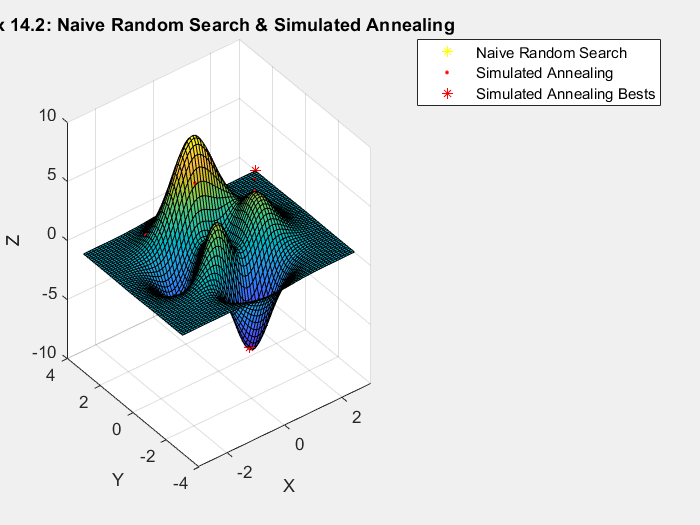

iteration_limit = 150;
for i=0:iteration_limit
    k = i;
    
    % Step 2: Pick Neighborhood point
    x_cur = rp(x_k(1),alpha);
    y_cur = rp(x_k(2),alpha);
    
    % Constrain values of x and y to the bounds of the function
    if (x_cur < lower_bound)
        x_cur = lower_bound;
    elseif (x_cur > upper_bound)
        x_cur = upper_bound;
    end
    
    if (y_cur < lower_bound)
        y_cur = lower_bound;
    elseif (y_cur > upper_bound)
        y_cur = upper_bound;
    end
    f_cur = f(x_cur,y_cur);
    
    % Step 3: Evaluate selected point using temperature
    temp = T_k(gamma,k);
    prob = pr(x_k,[x_cur; y_cur],temp);
    cointoss = rand(1);
    if cointoss <= prob
        x_k = [x_cur; y_cur];        
    end
    
    % Keep track of the best point found
    if(f_cur < min)
        min = f_cur;
        x_best = [x_cur; y_cur];
        h_anneal_best = scatter3(x_best(1), x_best(2), min, '*r'); 
    end
    
    % Plot current iteration point
    f_k = f(x_k(1),x_k(2));
    h_anneal = scatter3(x_k(1), x_k(2), f_k, '.r');
    
end
rotate3d on
legend([h_naive h_anneal h_anneal_best],{'Naive Random Search','Simulated Annealing','Simulated Annealing Bests'})
title('Ex 14.2: Naive Random Search & Simulated Annealing')
hold off


disp('Simulated Annealing')

Simulated Annealing


fprintf('Iterations: %d\n',iteration_limit);

Iterations: 150


fprintf('Minimum found %f at (x,y)=(%f,%f)',min,x_best(1),x_best(2));

Minimum found -6.052601 at (x,y)=(0.036058,-1.763256)

## Exercise 14.3

The function is defined as:

f = @(x,y) 3*(1-x).^2 .* exp(-x.^2-(y+1).^2) - 10*(x.*0.2-x.^3-y.^5).*exp(-x.^2-y.^2) - exp(-(x+1).^2-y.^2)/3;

% Plot in relevant interval
lower_bound = -3;
upper_bound = 3;
res = .1;
[x, y] = meshgrid(lower_bound:res:upper_bound,lower_bound:res:upper_bound);
z = f(x, y);
close all;
figure(2)
surf(x, y, z);
xlabel('X');
ylabel('Y');
zlabel('Z');

% Variable to hold figure handles for use later
h_pso = 0;
h_best = 0;

hold on

## Particle Swarm Optimization

The *Particle Swarm Optimization* algorithm works by defining a randomly generated population of points, with each point containing a velocity vector. In each iteration, the function is evaluated at the particles, and based on these evaluations a new set of particles with new velocities are created.

The number of particles is initially selected arbitrarily, then empirically changed:

particle_count = 50;

The *inertial* constant $\omega$ determines how the current velocity of a particle is weighted in the following iteration. Recommended value is just below 1.

w = 0.9;

The *cognitive* and *social* components $c_1$ and $c_2$ are constant, which determine how particles are directed towards "good" positions (personal and global respectively). Recommended values are $c_1 ,c_2 \approx 2$.

c1 = 1.99;
c2 = 1.99;

***Step 1:***

Initial points are generated:

k = 0;

% RNG within interval
rng = @(a,b,d) (b-a).*rand(d,1) + a;

% Initial random points (-3 to 3)
%ranp = @(xi, a, d) (xi - a) + 2*a*rand(d,1);
x_k = [rng(lower_bound,upper_bound,particle_count) rng(lower_bound,upper_bound,particle_count)];

% Initial random velocities (-1 to 1) 
%ranv = @(a, d) -a + 2*a*rand(d,1); 
v_k = [rng(-1,1, particle_count) rng(-1,1, particle_count)];

% Particle personal bests
p_k = x_k;

Evaluate all generated points:

% Function evaluation of generated points
fx_k = f(x_k(:,1), x_k(:,2));

% Determine initial global best
[fg_k, i] = max(fx_k);
g = [x_k(i,1) x_k(i,2)];

% Plot initial global best
scatter3(g(1), g(2), fg_k, '*m');

***Iterations (Step 2, 3, 4, 5 and 6):***

For each iteration, the positions and velocities are determined by:

${\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}+1\right)} =\omega \text{ }{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} +c_1 {\mathit{\mathbf{r}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} \circ \left({\mathit{\mathbf{p}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} -{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} \right)+c_2 {\mathit{\mathbf{s}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} \circ \left({\mathit{\mathbf{g}}}^{\left(\mathit{\mathbf{k}}\right)} -{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} \right)$,


$${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}+1\right)} ={\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)} +{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}+1\right)}$$


Where the vectors ${\mathit{\mathbf{r}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)}$ and ${\mathit{\mathbf{s}}}_{\mathit{\mathbf{i}}}^{\left(\mathit{\mathbf{k}}\right)}$ are randomly chosen uniformly in the interval $\left\lbrack 0:1\right\rbrack$.

Then for each iteration, the personal best of each particle and the global best for all particles are evaluated and updated.

iteration_limit = 100;
for k=1:iteration_limit
    % Step 2: Update positions and velocities
    r_k = rand(particle_count,2);
    s_k = rand(particle_count,2);
    
    % Update position of particles
    x_k = x_k + v_k;
    
    % Update velocity of particles
    v_k = w*v_k + (c1*r_k).*(p_k-x_k)+ (c2*s_k).*(g-x_k);
      
    % Step 3 & 4: Evaluate personal and global best for particles
    fg_k = f(g(1), g(2));
    for i=1:particle_count
        fx_k(i) = f(x_k(i,1),x_k(i,2));
        
        % Personal bests
        if fx_k(i) > f(p_k(i,1),p_k(i,2))
            p_k(i) = x_k(i);
        end
        
        % Global best
        if fx_k(i) > fg_k
            g = x_k(i,:);
            fx_k(i);
            h_best = scatter3(g(1), g(2), fx_k(i), '*m');
        end
    end
    
    % Plot particle swarm
    h_pso = scatter3(x_k(:,1), x_k(:,2), fx_k, '.w');
    axis([-3 3 -3 3 -8 10]);
    view(-45,30);
    pause(0.05);
end
h_end = scatter3(g(1), g(2), f(g(1),g(2)), '*r');
hold off;
rotate3d on
legend([h_pso h_best h_end],{'Particles','Global Bests','Final Best'})
title('Ex 14.3: Particle Swarm Optimization')

disp('Particle Swarm Optimization')
fprintf('Iterations: %d\n',iteration_limit);
fprintf('Maximum found %f at (x,y)=(%f,%f)',f(g(1),g(2)),g(1),g(2));
